# Handy Automated Neuroexplorer

Welcome to the Handy Automated Neuroexploere (HAN). This Matlab live script will guide you to the process of mapping cells to a reference atlas.

Matlab live scripts look slick and this script should help you process your first brains. However, live scripts are unfortunatly quite slow so after you get the hang of it, you might prefer to run this code from a standard .m file or to write your own analysis using these tools. In any case, use >>close all; and the 'Clear all Ouput' often. (Clear all Output is under the view tab in the toolbar.).

HAN uses a modified version of the Allen Brain Atlas as the refference atlas (see: [https://brain-map.org](https://brain-map.org)) Individual cells are recognized by applying a 2D convolution to the source image, thresholding it into a black and white image and then finding peaks. using AIDAhisto (see: [https://github.com/maswendt/AIDAhisto](https://github.com/maswendt/AIDAhisto)). Which is written by Niklas Pallast at the University Hospital in Cologne. The rest of the code was written by Johannes de Jong at UC Berkeley. For the newest version of HAN see: ...github.

### Input data

The input data should be one or more microscopy images of coronal mouse brain slices. The neuroexplorer probably does not work on rat brain slices. It's currently been tested on stiched brain slices taken with a Zeis Axio M2 microscope. A Coronal brain slice ends up being about .... x .... pixels. 8 bit single-chanel images are sufficient, but you might have better signal to noise on 16bit images.

If you want to analyse multiple images put them in a folder and name them simply 1, 2 ,3 etc. HAN does not sort the slices for you. There is a seperate function that will help you preprocess your dataset, it is called: process_source_dataset.m. See the function documentation to get instructions on how to run it. 

#### Examples:

These are example image files of a proper input dataset. Note that you should not include any other files in the same folder.

... examples ... TODO

### Output data

Each step in the script below produces it's own output data. In the end you will have the following files for each microscopy image (examples for slide 1):

- 1.jpeg (or tiff, or some other extention) This is the original microsopy image.

- 1.ref.tiff  This is the transformed reference atlas.

- 1_AIDAhis_settings.mat This file contains the settings what were used to identify cells on this source image

- 1_AIDAhis.txt This file contains the X and Y coordinates of identified cells in the microscopy image.

- 1_AIDAhis_eddited.txt The same as #3, but with false positive cells manually or automatically removed.

- 1_cells_mapped.txt X and Y coordiante of each identified cell in the framework of the reference atlas as well as the numerical identifyer of the brain region that they are in.

In addition the last code cells of this script produce data files with data from the entire brain. These are:

- X_han_whole_brain.txt (where x is the name of the mouse). As in 6 above, but for the entire dataset combined.

- X_han_whole_brain_corrected.mat. As in 1, but corrected for missing and/or double-sampled brain slices

- X_han_whole_brain_density.mat.  Instead of cells, this file will give the cell density for each pixel in the reference atlas (good for statistical analysis based on voxels)

#### Examples:

... TODO

### The reference atlas

The reference atlas used by HAN is a modified version of the Allen Brain Atlas. The original atlas can be found here:  [https://brain-map.org,](https://brain-map.org,) while the modified version, as well as the colormap are from: [https://github.com/cortex-lab/allenCCF.](https://github.com/cortex-lab/allenCCF.) Througout the script you can set the 'level' at which you want to inspect the atlas. This relates to .....

### Matlab Toolboxes you should have installed

- Computer Vision toolbox

# Start

To work through this live script, use** cmd-enter (Mac) or ctrl-enter (Windows)** to advance cell-by-cell or press the '**Run Section**' button in the toolbar.

### Empty the workspace

Incidently, this will remove all previous data you may have allready worked on before, so make sure you saved your date previously.

clc
clear
close all

### Add all files to the matlab path

This will make sure that HAN has access to all files. 

addpath('AIDAhisto_Matlab') % Rewriten version of AIDAhisto (Original code by Niklas Pallast).
addpath('functions and classes') % All other code the neuroexplorer uses
addpath('Allen Reference Atlas') % The modified reference atlas and its legend

# Select the data you want to work on

Here you will select the folder that containts all the microscopy images you want to work on. In addition, make sure the file extention is indeed the one you are using. Currently, the path is set to the example brain which contains .jpeg files of full-brain images covering the entire brain. The atlas is set to either the 10um atlas (1 pixel is 10um and very slide is 10um thick) or the 50um atlas (1 pixel is 50um and every slide is 50um thick). Note that you should do the entire brain with the same atlas.

### Select the source data

path_to_the_brain = 'test/example_brain/'
file_ext = '.jpeg';
atlas_type = '50um atlas';
atlas_thickness = 50; % thickness of the atlas slices in µm

Note that the files should be numbered (see the example_brain folder for examples). You also have to select which specific slide you want to work on. For instance, if you want to process slide 1 till 10, you should set: >> slice_numbers = [1:10];  And if you only want to process slide 12, it should be slice_numbers = [12];  You can simply re-run this code cell to select different slices and process them using the code cells below. If you process a slide that was previously analysed, the old analysis will be overwritten.

slice_numbers = [1:10];

### Set other analysis variables

Other setting include wether or not you want to save the data (or just quickly visualize) and an arbitrary threshold value to identify cells. The lower the value, the more cells you will find, but you will also find more noise.

cell_threshold_value = 1; % The threshold above which cells are identified is automatically calculated, but you can 'weigh' it here. Use trial and error.
cell_size = 3; % How many pixels a cell is wide (on average) in your pictures (should be at least 3).
channel_number = 1; % If your source images are multi-chanel images (for instance RGB = red, green, blue) select the channel you want to do the analysis in here.
save_data = true; % Save the data or just quickly visualize
plot_data = true; % Show data after each analysis
start_slice = 190; % The first reference atlas slice that will be shown
slice_thickness = 100; % In µm, used to predict the next most likely atlas slice and to figure out if any slices are missing

### Where we will save the final data

whole_brain_file = 'Whole_Brain_HAN_new.txt'; % The filename for the final dataset

# Build reference atlas slices for each microscopy image

This cell will open the GUI that you will use to build the reference atlas pictures. If save_data is true, all reference atlas pictures will be stored in the same folder as the microscopy source images. There is no need to process all brain slices in one go. Set the variable slice_numbers to select the slices you want to work on. If you don't like one specific reference atlas picture, you can just re-run this cell and it will automatically be overwritten. If you allready made reference pictures and just want to continue identifying and counting cells, simply skipp this code cell.

The GUI looks like this: (note the similarly numbered landmarks on both pictures.)

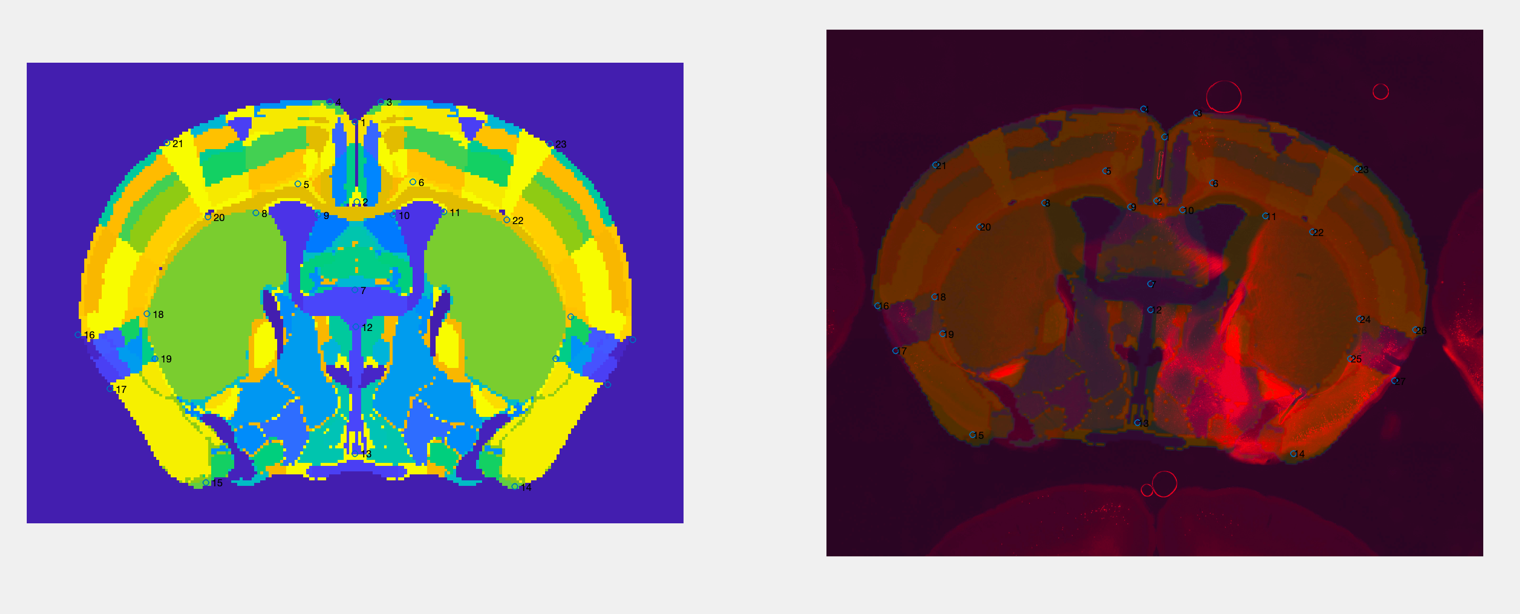

Work trough it as follows:

Use the **arrow keys** to select the appropriate atlas slice. Note that in general this live script will go to the correct atlas slice to get evenly-spaced data. If you have to use the arrow keys a lot, your slices are not in the right order, they are not of equal thickness or you have a lot of missing slices (note that we will deal with missing slices below).

Use the **space bar** to go to landmark mode and use the mouse to put landmarks on both the atlas and the source image. The landmarks should be put in the same sequence. Use **n** to see the landmark numbers and if you think you made a mistake, use **d** to delete the last landmarks and **f** to delete all of them. In principle 4 landmarks in a latin cross shape is enough to align the atlas to the source image, but it is probably a good idea to put a few more. Make sure to put them especially close to areas where you see a lot of cells in your source image, because you want your cells to end up in the right brain region.

To get a better look at the source image, use** c** and **x** to increase/decrease contrast and use** b** and **v** to increase/decrease brighness. Use **o** to reset the original.

Use** t** to transform the atlas and **s** to show it or make it invisible. You can repeat this process multiple times, just keep putting landmarks where you feel the reference and the souce image don't properly align. Keep pressing **t** to calculate a new reference.

Finally, to accept the reference, press '**enter/return**'.

include_slices = slice_numbers; % Default from above, but feel free to change to run only a selection of the slices.

for slice = include_slices
    
    % Grab the filename
    filename = [path_to_the_brain num2str(slice) file_ext];
    
    % Figure out if we should save the data
    save_str = 'skipp'; if save_data; save_str='save data'; end
    
    % Make the reference
    [reference, training_data] = HAN_make_reference(filename, 'start slice', start_slice, atlas_type, save_str);
    
    % If no reference was accepted, skip this slide
    if reference == 0
        warning(['No reference accepted for slide ' num2str(slice') '. Consider deleting the source image file from the folder if you don''t want to include it.'])
        disp('If you DO want to include it, uste HAN_make_reference to make a reference for this source image.')
        continue;
    end
    
    % Grab the start_slice for the next run
    if strcmp(atlas_type, '10um atlas')
        start_slice = training_data.ref_nr - round(slice_thickness/10); % (Atlas slices are 10µm thick)
    elseif strcmp(atlas_type, '50um atlas')
        start_slice = training_data.ref_nr - round(slice_thickness/50); % (Atlas slices are 50µm thick)
    end
            
end

The output file from this code cell is:

#### X_ref.tiff

# Find cells

This code cell will use AIDAhisto to identify cells and assign them to different brain regions. If save_data is set to true, it will store a .txt file that contains the X and Y coodiantes of all the cells it found 

Note that AIDAhisto takes a number or parameters, several of which are allready filled out below. The parameters are:

CHANNEL    - color channel RGB (int) 1 - 3 

MIN_DIST   - min distance between cells (double)

BAR_FILTER - set to 1 for detecting non circular cells

DARK_PEAKS - set to 1 for detecting dark cells in bright background (int)

SAVE_DATA  - set to 0 to avoid saving peak coordinates (.txt)

THRES_W    - weighting factor for isodata threshold - default 10

Note: The DARK_PEAKS paramters is meant for source images where the target cells are darker then then the background. However, since the analysis is done on 2D convoluted images, it might just as well be used for bright cells and that actually seems to work really well often times.

include_slices = slice_numbers; % Default from above, but feel free to change to run on only a selection of the slices

for slice = include_slices
    % Output text
    disp(['Working on slice ' num2str(slice)])
    
    % Grab the path
    full_file = [path_to_the_brain num2str(slice) file_ext];
    ref_path = [path_to_the_brain num2str(slice) '_ref.tiff'];
    
    % Use AIDAhisto to find cells
    fprintf("Processing wholebrain slice...\n")
    AIDAhisto(full_file,...
        'WIDTH', cell_size,...
        'DARK_PEAKS', 1,...
        'BAR_FILTER', 1,...
        'CHANNEL',channel_number,...
        'THRES_W', cell_threshold_value,...
        'SAVE_DATA', save_data,...
        'PLOT_DATA', plot_data);
    
    % Plot the results if the user requested that. Plot on top of the
    % transformed reference atlas.
    if plot_data
        cell_data = [path_to_the_brain num2str(slice) '_AIDAHis.txt'];
        try
            han_plot_ARA_cells(cell_data, ref_path);
        catch
            disp('Can''t plot the cells on top the reference, because no reference for this slice exist yet')
        end
    end
end

% To prevent Matlab from becoming super slow, especially when running this in a live script, close everything
%close all force


If you plotted the data you can scroll to the pictures (depending on your live-editor configuration they are to the right or above of this text) and verify that AIDA histo and the make_reference did a good job. If you don't like individual images redo the analysis on these slices, the old data will automatically be overwritten. For instance, if you want to redo slide 9, 31 and 82 set the variable slice_numbers (all the way at the top) to: >>slice_numbers = [9 31 82]; and re-run the code cells where you made the reference atlas or the AIDAhisto cells using different settings (for instance after you changed the threshold value). You don't have to re-run both, you can also only re-run one part of the analysis and only the old data associated with that part will then be overwritten.

Note that altough it's convenient to explain all the code like this, Matlab live scripts will become **super slow** if you display many of the brain slices. Consider running this code directly from the comand line or from a .m file.

The output files from this code cell are:

#### X_AIDAhis.png

#### X_AIDAHis.txt

# Manually removing errors

Note that you don't have to remove cells that are* outside *the brain slice (for instance because air bubles were identified as cells), these will be deleted automatically.

- TO DO: explanation use **left mouse button **to zoom, **right mouse button** to remove cells. use **u** to undo. Use **p** to set a different threshold and find more/less cells. Same keys as above to adjust brightness, contrast (**x,c,v **&**b**). Use **l(L)** to flip the slice and **enter** to accept. You can view the alligned reference by pressing **s**, but you can only change it using the code cell above.

include_slices = slice_numbers; % Default from above, but feel free to change to run on only a selection of the slices

for slice = include_slices
    % Output text
    disp(['Working on slice ' num2str(slice)])
    
    % Grab the path
    full_file = [path_to_the_brain num2str(slice) file_ext];
    
    % Open the manual inspector
    flag = HAN_manual_inspector(full_file, 'save data');
end

The output file of this code cell is:

#### X_AIDAhis_edited.txt

(any older version of this file will be overwriten)

# Storing cells in the framework of the reference atlas

So we found cells and assigned them to a brain region. However, if we want to make 3D visualizations of our found cells or do statistical comparison of different brains, it makes more sense to store the coordiantes or all the cells we found relative to the coordinates of the reference atlas. The following code cell does exactly that. The output is a .txt file with 6 columns of data. Every row is one 1 cell, the 6 columns are:

- The X coordinate of the cell in the reference atlas.

- The Y coordiante of the cell in the reference atlas.

- The slice of the reference atlas this cell is assigned to (Z coordinate).

- The X coordinate of the cell in the microscopy image.

- The Y coordinate of the cell in the microscopy image.

- The identifyer of the brain region this cell is in.

include_slices = slice_numbers; % Default from above, but feel free to change to run on only a selection of the slices

% Figure out if we should plot and/or save data
save_str = 'skipp'; if save_data; save_str='save data'; end
plot_str = 'skipp'; if plot_data; plot_str='plot data'; end

% NOTE: map_cells_to_atlas will automaticaly used the edited file if it
% exists. However you can force it to use the original file (the direct
% output of AIDAHis that did not go through manual editing.) by including
% the argument 'no editing'.

for slice = include_slices   
    
    % Grab the path
    full_file = [path_to_the_brain num2str(slice) file_ext];
    
    % Perform the mapping
    HAN_map_cells_to_atlas(full_file, save_str, plot_str); 
end

If you are plotting the data, you should see a nice overview of the cells mapped to the atlas. But again, note that this might make the live script run super slow.

The output file of this code cell is:

#### X_cells_mapped.txt

# Collecting all the cells into one data file

Here we will collect all the data in the X_cells_mapped.txt files into one bit variable. This file can then be used for 3d plotting and for making the graphs. Note that you have to pick a filename for the final data file and that it will not be stored in the same folder as the microscopy images but instead in your current working directory. 

include_slices = slice_numbers; % Default from above, but feel free to change to run on only a selection of the slices

% PUT THE FILENAME HERE
% (will now automatically use the name from above)
new_filename = whole_brain_file;

% Figure out if we should plot and/or save data
save_str = 'skipp'; if save_data; save_str='save data'; end
plot_str = 'skipp'; if plot_data; plot_str='plot data'; end

% Output data
HAN_collect_all_slices(new_filename, path_to_the_brain, include_slices, save_str, plot_str, 'level', 3);
    

The output file of this code cell is:

#### whole_brain.txt

# Correcting for missing slices

There might be slices missing from the dataset. For instance because something went wrong during the processing of the brain. Oftentimes the brain has to be glued to a backplate of some sorts and this usually results in some missing slices. This code cell will do the following:

- Using the thickness of the microscopy slices and the reference atlas slices selected by the user it will figure out which slices are missing.

- It will then create those slices using the following tactic: it will look at all the brain areas in the missing slice and estimate how many cells *should* be there based on the adjecent (not missing) slices.

Note that the new slices are reasonable estimations that are however only as good as the input data. If there are to many missing slices, or not enough cells, the estimations will have very high uncertainty. However, if there is a high number of cells (ten thousands) and not to many missing slices, they should be very precice.

% Currently, this function only gives an overview of the dataset, it does
% not change anything
HAN_find_missing_slides(whole_brain_file, slice_thickness, atlas_thickness);

# Making Graphs

... Output and Output normalized to total cels.

data = HAN_make_plots(whole_brain_file, 'level', 6, 'min cells', 100);

# Present 3D brain

To Do... write text

% The path to the data file
brain_filename = whole_brain_file;

% What level do you want to show the brain regions?
%(The higher the number, the more the detail)
level = 6;

% What is the minimum amounth of cells that should be in a brain region?
%(Cells in regions with fewer than this number of cells are labeled other.)
min_cells = 100;

% Show the entire brain in 3D
HAN_show_whole_brain(brain_filename,...
    'level', level,...
    'min cells', min_cells);



# Calculate voxel-based cell density

to do...